# **Robust Metabolic Transformation Analysis - rMTA**

## Luis V. Valcarcel, University of Navarra, TECNUN School of Engineering, Spain

## Francisco J. Planes, University of Navarra, TECNUN School of Engineering, Spain

## Reviewer(s): 

## INTRODUCTION

Metabolic Transformation Algorithm (MTA) [1] aims to identify targets that transform a disease metabolic state back  into a healthy state, with potential application in any disease where a  clear metabolic alteration is observed.

Robust Metabolic Transformation Algorithm (rMTA) [2] is the natural evolution of such an algorithm, removing the induced bias and studying all the possible outputs of metabolic perturbations; to discover how easy is for a perturbation to drive the metabolism into target or in the opposite direction. This can be seen in Figure 1. Our desired case is (**Figure 1A**), in which MTA  and MTA targeting the opposte direction can only drive the metabolism into the desired direction. This is produced when the Transformation Scores (TSs) after gene knockout are skewed to the healthy direction in both the best-case (bTS) and worst-case scenario (wTS); (**Figure 1B**) TSs are similar in value and skewed to the opposite direction in the best-case and worst-case scenario and, therefore, under-determination arises; (**Figure 1C**) The same as (**Figure 1B**), but TS is higher in the best-case scenario and skewed to the healthy direction when MOMA is applied (mTS > 0). Under-determination is resolved here using mTS (MOMA TS), which generates the perturbation without any prior knowledge of the desired flux change direction.

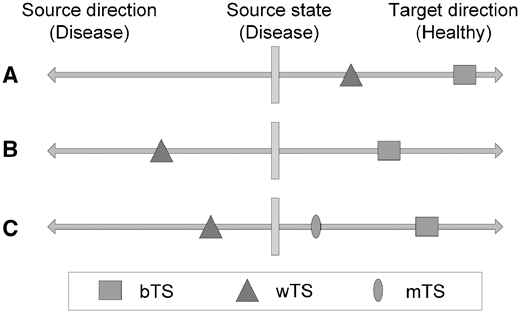

**Figure 1. Illustration of the problem addressed by rMTA**. 

In order to show the use of the tool, we are going to use data from controlled gene knockout (*RRM1*) experiment in a human cell line with RPMI cultture media. The experiment reference is GSE9345 [3]. In such experiment, we are going to predict that *RRM1* drives the source state(WT) into the target (RRM1-knockout) state. This case is shown in table 2 of the rMTA article.

## EQUIPMENT SETUP

## Initialize The Cobra Toolbox and select the solver (~25 sec)

If necessary, initialise the Cobra Toolbox:

clear

initCobraToolbox(false) % false, as we don't want to update



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2021
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.13.3).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > TranslateSBML is installed and working properly.
 > Configu

Note that the approaches to calculate MTA and rMTA scores it is necessary to solve problems that are based on Mixed Integer Quadratic Programming (MIQP). The solver selected will be Cplex, althought it has also been tested with gurobi.

changeCobraSolver('ibm_cplex', 'all');


 > changeCobraSolver: IBM ILOG CPLEX interface added to MATLAB path.
 > The solver compatibility is not tested with MATLAB R2018b.
 > changeCobraSolver: Solver for LP problems has been set to ibm_cplex.

 > changeCobraSolver: IBM ILOG CPLEX interface added to MATLAB path.
 > The solver compatibility is not tested with MATLAB R2018b.
 > changeCobraSolver: Solver for MILP problems has been set to ibm_cplex.

 > changeCobraSolver: IBM ILOG CPLEX interface added to MATLAB path.
 > The solver compatibility is not tested with MATLAB R2018b.
 > changeCobraSolver: Solver for QP problems has been set to ibm_cplex.

 > changeCobraSolver: IBM ILOG CPLEX interface added to MATLAB path.
 > The solver compatibility is not tested with MATLAB R2018b.
 > changeCobraSolver: Solver for MIQP problems has been set to ibm_cplex.
 > changeCobraSolver: Solver ibm_cplex not supported for problems of type EP. No solver set for this problemtype 
 > changeCobraSolver: Solver ibm_cplex not supported for problems 

## STEP 1: load the information to generate the reference flux

The first step of rMTA algorithm is the reconstruction of the model for a specific tissue and sample the feasible flux space to calculate a reference flux. 

For this study we have used Recon1, using the RPMI-1640 culture media. We have used FVA to find all blocked reactions and remove them.

filename_metabolic_model = 'Recon1_RPMI1640_FVA.mat';
model = readCbModel(fullfile('Data',filename_metabolic_model))

Each model.subSystems{x} has been changed to a character array.


model = struct with fields:
                      S: [1239×1913 double]
                   mets: {1239×1 cell}
                      b: [1239×1 double]
                 csense: [1239×1 char]
                   rxns: {1913×1 cell}
                     lb: [1913×1 double]
                     ub: [1913×1 double]
                      c: [1913×1 double]
              osenseStr: 'max'
                  genes: {1905×1 cell}
                  rules: {1913×1 cell}
              metKEGGID: {1239×1 cell}
                grRules: {1913×1 cell}
             rxnGeneMat: [1913×1905 double]
    rxnConfidenceScores: [1913×1 double]
             subSystems: {1913×1 cell}
            description: 'Recon1_RPMI1640_FVA.mat'
                modelID: 'Network'
                      C: [0×1913 double]
                   ctrs: {0×1 cell}
                      d: [0×1 double]
                 dsense: [0×1 char]
                ChEBIID: {1239×1 cell}
              ECNumbers: {1913×1 cell}
            InChIStri


% transcript separator: there are some models (as Recon X) in which genes are
% used at transcript level, not in gene level. Transcript separator is a variable
% to join all transcripts of the gene and work at gene level.
transcript_separator = '.';

fprintf('\tMetabolic model uploaded\n');

	Metabolic model uploaded


Then we import the gene expression data and reconstruct the model, using iMAT. This data has been obtaind in R using GEO accesion tools and performing the data preprocessing proposed for the Affymetrix Human Genome U133A 2.0 Array, using ARIMA, and the discretization into Highly , medium or lowly expressed proposed by the authors of iMAT[4]. This is explained in detail in the rMTA article in detail [2].

filename_onmics = 'GSE93425_Recon1_discret_iMAT_07_100.txt';
onmic_data = readtable(['Data',filesep,filename_onmics],'ReadVariableNames',true);

% Traduce onmic data from gene level to reaction level
aux_table = table(strtok(model.genes,transcript_separator),model.genes,'VariableNames',{'ENTREZ_ID' 'transcript'});
onmic_data = outerjoin(aux_table, onmic_data, 'Keys','ENTREZ_ID');
head(onmic_data)

ans = 8×6 table
    ENTREZ_ID_aux_table    transcript    ENTREZ_ID_onmic_data    scramble    siRRM1    siRRM2
    ___________________    __________    ____________________    ________    ______    ______

          '100'            '100.1'             '100'                 1          1         1  
          '10005'          '10005.1'           '10005'               0          0         0  
          '10005'          '10005.2'           '10005'               0          0         0  
          '10005'          '10005.3'           '10005'               0          0         0  
          '10007'          '10007.1'           '10007'               1          1         1  
          '10020'          '10020.1'           '10020'               0          1         0  
          '10026'          

% prepare data for iMAT algorithm
expressionData = struct();
expressionData.gene = onmic_data.transcript;
expressionData.value = onmic_data.scramble*2;
[onmic_rxn_data.expression, onmic_rxn_data.parsedGPR] = mapExpressionToReactions(model, expressionData);
onmic_rxn_data.expression(onmic_rxn_data.expression == -1) = 0; % not mapped reactions as 0 (medium expressed = No information)
fprintf('\tOmnic data transformed from gene level to reaction level\n');

	Omnic data transformed from gene level to reaction level


In the original formulation of the paper and in our implementation, the algorithm selected for tissue reconstruction is iMAT. iMAT is computationally expensive and it's solution is not unique, so we provide the result of iMAT implementation.

% code for iMAT solver
options  =struct();
options.solver = 'iMAT';   
options.threshold_lb = + 1;
options.threshold_ub = - 1;
options.expressionRxns = onmic_rxn_data.expression;
options.timelimit = 30;
options.printLevel = 1;
options.numWorkers = 2;
options.numThreads = 2;

% run iMAT
tic
%tissueModel_scramble = createTissueSpecificModel(model, options, 1);
load(['Data' filesep 'tissueModel_scramble.mat'])
TIME.iMAT = toc    

TIME = struct with fields:
    iMAT: 0.0792


The reconstructed model is sampled to obtain 2000 possible flux states, which can define a reference flux state. Sampling is computationaly expensive and stocastic, so we provide the solution of the article

% Sampling Method and options
sampling_method = 'ACHR';	%{('CHRR'), 'ACHR'}
sampling_options = struct();
sampling_options.nWarmupPoints = 5000;      	% (default)
sampling_options.nPointsReturned  = 2000;   	% (default)
sampling_options.nStepsPerPoint  = 500;    	% (default = 200)

% Now COBRAtoolbox include sampler
tic
%[modelSampling,samples] = sampleCbModel(tissueModel_scramble,'sampleFiles',sampling_method,sampling_options);
load(['Data' filesep 'Sampling_results.mat']);
TIME.sampling = toc;

sampleStats = calcSampleStats(samples);

Processing sample 1


% from reduced index to model.rxns index
idx = zeros(size(samples,1),1);
for i = 1:numel(idx)
    try
        idx(i) = find(strcmp(model.rxns,modelSampling.rxns{i}));
    catch
        idx(i) = find(cellfun(@length,strfind(model.rxns,modelSampling.rxns{i})));
        sampleStats.mean(i)=-1*sampleStats.mean(i) %Those reactions are reversed;
    end
end
rxnInactive = setdiff(1:length(model.rxns),idx); % inactive reactions
fields = fieldnames(sampleStats);
for i = 1:numel(fields)
    aux = sampleStats.(fields{i});
    sampleStats.(fields{i}) = zeros(size(model.rxns));
    sampleStats.(fields{i})(idx) = aux;
    clear aux
end

% resize the samples matrix
aux = samples;
samples = zeros(size(model.rxns,1),sampling_options.nPointsReturned);
samples (idx,:) = aux;
clear aux;   

Finally we can set a reference flux

Vref = sampleStats.mean;

## STEP 2: load the information of the differentially expressed genes and calculate upregulated and downregulated reactions

Once we have defined the source genotype, in most of the applications the disease state, we need to calculate the required changes in order to reach the objective state, in most of the cases the healthy state.

This is a particular case, in which we start in a Wild Type / scramble state (source) and try to calculate the gene Knock-out which reaches the mutant state (target). This is a controlled KO which allows us to evaluate the use of rMTA.

The differential expression of Scramble vs siRRM1 has done in R, using GEO accession tool ARIMA and limma, with the default parameters (this is explained in detail in the rMTA article in detail [2]).

% Differentially expressed genes
% Neccesary variables: 'gene','logFC','pval'
% 'Gene_ID' must be the same nomenclature as the metabolic model
% Study must be uploaded as DISEASE VS HEALTHY/CONTROL
filename_differentially_expressed_genes = 'scramble-siRRM1_differ_exp_met_genes.txt';
logFC_requiered = 0; % change if necesary
pval_requiered = 0.1; % change if necesary

differ_genes = readtable(fullfile('Data',filename_differentially_expressed_genes),...
    'ReadVariableNames',true);

differ_genes.pval = differ_genes.adj_P_Val; % requiered variable by code
differ_genes.gene = differ_genes.ENTREZ_ID; % requiered variable by code

% Here we should obtain an array similar to rxnHML, in which we have the
% information of whatever an expresion should increase, decrease or nothing
% (+1)R_f    (-1)R_b     (0)unchanged
% This vector is called rxnFBS (Forward, Backward, Unchanged)

rxnFBS = diffexprs2rxnFBS(model, differ_genes, Vref, ...
    'SeparateTranscript', transcript_separator, 'logFC', logFC_requiered, 'pval', pval_requiered);

	Gene expression changes calculated
	There are 204 trainscripts that are differentially expressed
	There are 161 genes that are differentially expressed
	Reaction expression changes calculated
	There are 159 reactions that are differentially expressed



% change in rxnFBS all those reactions that are not active
%  it is not possible to predict the direction of the change
rxnFBS(rxnInactive) = 0;
fprintf('\tThere are %u reactions that are differentially expressed after curation\n',sum(rxnFBS~=0));

	There are 76 reactions that are differentially expressed after curation


## STEP 3: run rMTA algorithm, implemented in a function available in COBRA toolbox

Both MTA and rMTA use the same parameters: epsilon and alpha:

% Define alpha values to calculate rMTA
alpha_values = [0.66];  % (default range of values) % better to have more values
%  It has been included 0.66 as it is the original value used in the
%  original paper ('Yizhak et al, 2013')
num_alphas = length(alpha_values);

% Calculate epsilon, different for each reaction and with a minimum required change of 1e-3 (%default)
epsilon = calculateEPSILON(samples, rxnFBS);

One we have defined the parameters required by rMTA/MTA, we can use the COBRA function to calculate the transformation score (TS score):

changeCobraSolver('ibm_cplex', 'all')


 > changeCobraSolver: IBM ILOG CPLEX interface added to MATLAB path.
 > The solver compatibility is not tested with MATLAB R2018b.
 > changeCobraSolver: Solver for LP problems has been set to ibm_cplex.

 > changeCobraSolver: IBM ILOG CPLEX interface added to MATLAB path.
 > The solver compatibility is not tested with MATLAB R2018b.
 > changeCobraSolver: Solver for MILP problems has been set to ibm_cplex.

 > changeCobraSolver: IBM ILOG CPLEX interface added to MATLAB path.
 > The solver compatibility is not tested with MATLAB R2018b.
 > changeCobraSolver: Solver for QP problems has been set to ibm_cplex.

 > changeCobraSolver: IBM ILOG CPLEX interface added to MATLAB path.
 > The solver compatibility is not tested with MATLAB R2018b.
 > changeCobraSolver: Solver for MIQP problems has been set to ibm_cplex.
 > changeCobraSolver: Solver ibm_cplex not supported for problems of type EP. No solver set for this problemtype 
 > changeCobraSolver: Solver ibm_cplex not supported for problems 

ans = logical
   1


% execute the code
tic
[TSscore, deletedGenes, Vres] = rMTA(model, rxnFBS, Vref, alpha_values, epsilon, ...
    'timelimit', 60, 'SeparateTranscript', transcript_separator, 'printLevel', 1);

========  rMTA algorithm  =========
Step 0: preprocessing: 
Calculate Gene Knock-out matrix
100%    [........................................]
	GeneKOMatrix calculated
-------------------
Step 1 in progress: the best scenario 
	Start rMTA best scenario case for alpha = 0.66 
	cplex model for MTA built
    MIQP Iterations for bMTA
100%    [........................................]
	All MIQP problems performed
	Step 1 time: 119.66 seconds = 1.99 minutes
-------------------
Step 2 in progress: MOMA
	QPproblem model for MOMA built
    QP Iterations for MTA
100%    [........................................]
	All MOMA problems performed
	Step 2 time: 35.68 seconds = 0.59 minutes
-------------------
Step 3 in progress: the worst scenario 
	Start rMTA worst scenario case for alpha = 0.66 
	cplex model for MTA built
    MIQP Iterations for wMTA
100%    [........................................]
	All MIQP problems performed


TIME.rMTA = toc  

TIME = struct with fields:
        iMAT: 0.0792
    sampling: 0.1070
        rMTA: 293.3228


## STEP 4: save results in an Excel for study

First of all, we are going to clean the Results folder and save the results from this tutorial

delete(['Results' filesep 'H929_siRRM1_case.mat'])
delete(['Results' filesep 'H929_siRRM1_case.xlsx'])
save(['Results' filesep 'H929_siRRM1_case.mat'])

Secondly, we can use information from Biomart to provide additional information of the genes, like the ENSEMBL ID, gene name, symbol,...

% gene information
filename3 = 'Data\GeneInfo_HomoSapiens_ENSEMBL_103.txt';
biomart_genes = readtable(filename3,'ReadVariableNames',true);

biomart_genes.NCBIGene_formerlyEntrezgene_ID = cellfun(@num2str, num2cell(biomart_genes.NCBIGene_formerlyEntrezgene_ID), 'UniformOutput', 0);
[~, idx] = ismember(deletedGenes, biomart_genes.NCBIGene_formerlyEntrezgene_ID);
idx = idx (idx>0);
gene_info = biomart_genes(idx,:);
gene_info.gene = gene_info.NCBIGene_formerlyEntrezgene_ID;
geneID=table(deletedGenes, 'VariableNames', {'gene'});
gene_info = outerjoin(geneID,gene_info,'MergeKeys',true);


rMTAsaveInExcel(['Results' filesep 'H929_siRRM1_case.xlsx'], TSscore, deletedGenes, alpha_values, ...
    'differ_genes', differ_genes,'gene_info', gene_info, 'RankingGeneID' ,'6240')

	Process results for alpha = 0.66 
	Selected the "550" best solutions
	Write xls for alpha = 0.66 


	Write selection of best genes


	SUMMARY


DONE


Obtained results should show that RRM1 has been predicted number 28 in the ranking, using an alpha of 0.66

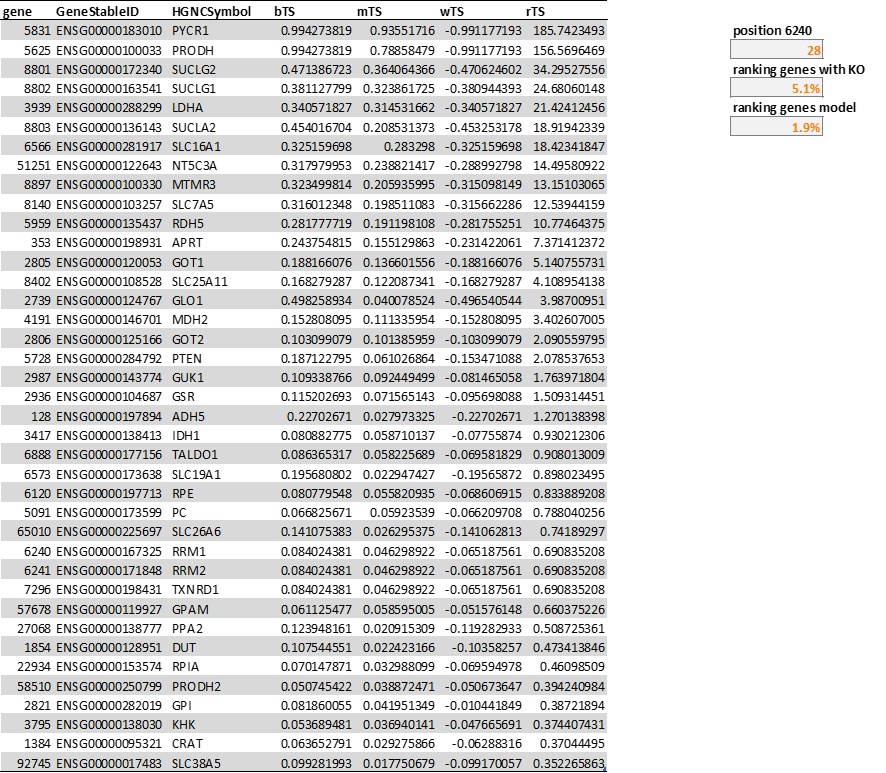

## TIMING

- Equipment Setup: ~25 sec.

- Load the information and process it: ~5 sec.

- Reconstruction: ~1-5 min.

- Sampling: ~15 min.

- rMTA: ~5 min 

 TIME

TIME = struct with fields:
        iMAT: 0.0792
    sampling: 0.1070
        rMTA: 293.3228


Note that it is advisable to have EXCEL installed, in order to save all the results in an easily understandable format.

## REFERENCES

*1. *Yizhak, Keren, et al. "Model-based identification of drug targets that  revert disrupted metabolism and its application to ageing." *Nature communications* 4.1 (2013): 1-11.

*2. *Valcárcel, Luis V., et al. "rMTA: robust metabolic transformation analysis." *Bioinformatics* 35.21 (2019): 4350-4355.

*3. *Sagawa, Morihiko, et al. "Ribonucleotide reductase catalytic subunit M1  (RRM1) as a novel therapeutic target in multiple myeloma." *Clinical Cancer Research* 23.17 (2017): 5225-5237.

*4. *Shlomi, Tomer, et al. "Network-based prediction of human tissue-specific metabolism." *Nature biotechnology* 26.9 (2008): 1003-1010.